# Taxonomic Classification based on Codon Usage Bias Levels

## 1. Theoretical Background

The construction plan of every life-form is stored in the form of the four nucleotides Adenine, Guanine, Thymine (Uracil), or Cytosine as DNA or RNA inside a cell. In a gene, these four nucleotides can be clustered in so-called codons. Each codon consists of three nucleotides of the previously named nucleotides, resulting in a total number of 64 codons. Every codon decodes for one of the 21 proteinogenic amino acids which are used to synthesize proteins and polypeptides. For certain amino acids, there is more than one codon, as this can be shown for the amino acid Arginine, which is coded by six different codons. Due to the evolutionary development of organisms, usually not all 64 codons are used to encode the genetic information with the same frequency. This leads to an additional regulation during translation, based on the concentration of the corresponding tRNA molecules, which are coupled to the corresponding amino acids. [1]

Especially in the study of evolution and in the classification of unknown DNA-sequences, codon usage bias contains information about the genetic composition and the synonymous proteinogenic properties of an organism. The awareness of codon usage bias for an organism builds the linking part between proteinogenic sequence analysis and genomic analysis. This leads to new scientific approaches in evolutionary research and phylogenetic reconstruction of already known and unknown taxa. [2]

As a specific example, the characterization of biodiversity in environmental specimens (e.g. water or soil samples) is named here. Therefore the so-called Metabarcoding method is used to reconstruct sequence profiles for species identification in mixed DNA-samples. Thereby huge sequencing data amount is generated and needs to be characterized. If the mixed DNA-sample also contains DNA-fragments from unknown organisms, a first characterization into the right domain is an essential first step.[3]

## 2. Data Structure 

The data set was provided via E-mail by Dr. Bohdan Khomtchouk from the University of Chicago at the request of this project group in a .csv format. Information about the structure of the data set is used from the UCI Machine Learning Repository from the following URL: [https://archive.ics.uci.edu/ml/datasets/Codon+usage](https://archive.ics.uci.edu/ml/datasets/Codon+usage) (Last call of URL on 08.12.2020). Due to server problems, at the time on which this report was created, the data set was not publicly available.

The following bullet points show the structure of the data set: 

- Observations: 13028

- Column1: Kingdom

- Column2: DNAtype

- Column3: SpeciesID

- Column4: NCodons

- Column5: SpeciesName

- Column6-69: one column for each one of the 64 codons

In the Kingdom column, for every observation, the corresponding taxonomic order is described with a three-letter code. In total, 11 different classification attributes are listed: arc (archaea), bct (bacteria), phg (bacteriophage), plm (plasmid), pln (plant), inv (invertebrate), vrt (vertebrate), mam (mammal), rod (rodent), pri (primate), vrl (virus). An overview over the taxonomic structure of the observations in the dataset is given in Figure 1. 

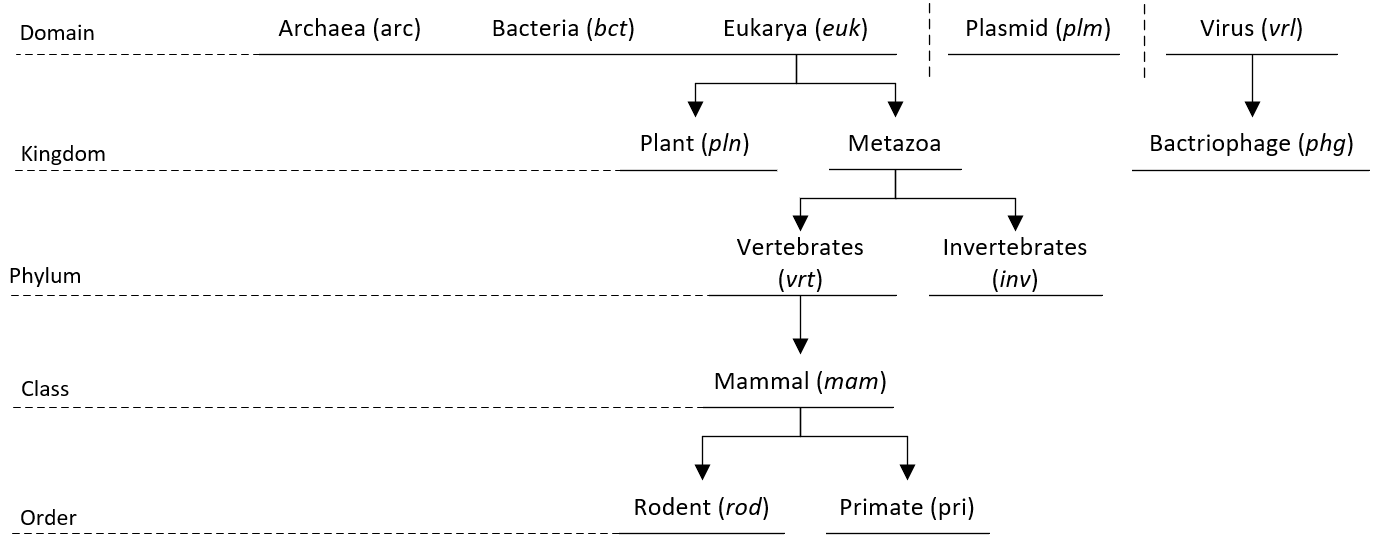

**Figure 1:**  Schematic overview of the taxonomic levels of the different observational sequences in the dataset.[Fgure created with MS Visio Professional]

The listed codon frequencies for each of the 64 codons in every observation are normalized to the given number of total codons (Column 4). Due to this normalization, the frequencies for every observation sum up to 1. Further information about the source of the data and a more detailed description of the datatypes of every attribute is given in the corresponding publication. [4]

## 3. Project goal and algorithm introduction

### 3.1 Goal

The goal of this project is the implementation of a machine learning algorithm, for the taxonomic classification of DNA-sequences based on the codon usage frequency. Therefore the kNN and the Random Forest algorithms are compared to their accuracy and precision. These criteria should be used to determine the suitability of the two algorithms for a potential classification application of DNA-sequences on their codon usage frequency into phylogenetic domains.

### 3.2 kNN and Random Forest algorithm

The underlying theory of the kNN algorithm is based on the classification by comparing the similarity of a data point to its neighbors. Therefore, some kind of measurable parameter needs to be used to calculate the distance between two considered datapoints. In this project, the often-used dissimilarity function of the Euclidean distance is used for the implementation of the kNN algorithm.[5]

The Random Forest algorithm is based on the so-called bootstrap aggregation (Bagging) method in combination with decision trees. This method allows for picking random samples from the training data for a decision tree. Thereby, for every observable feature a ‘Yes’- or ‘No’- decision is made, where the output is a class assignment. After evaluating the classification outcome of numerous amount of these decision trees, the final classification is made by selecting the class, which got the most classifications from the trees.[6]

## 4. Experimental Approach and Methodic Overview

A graphical overview of the methodical approach is given in Figure 2. 

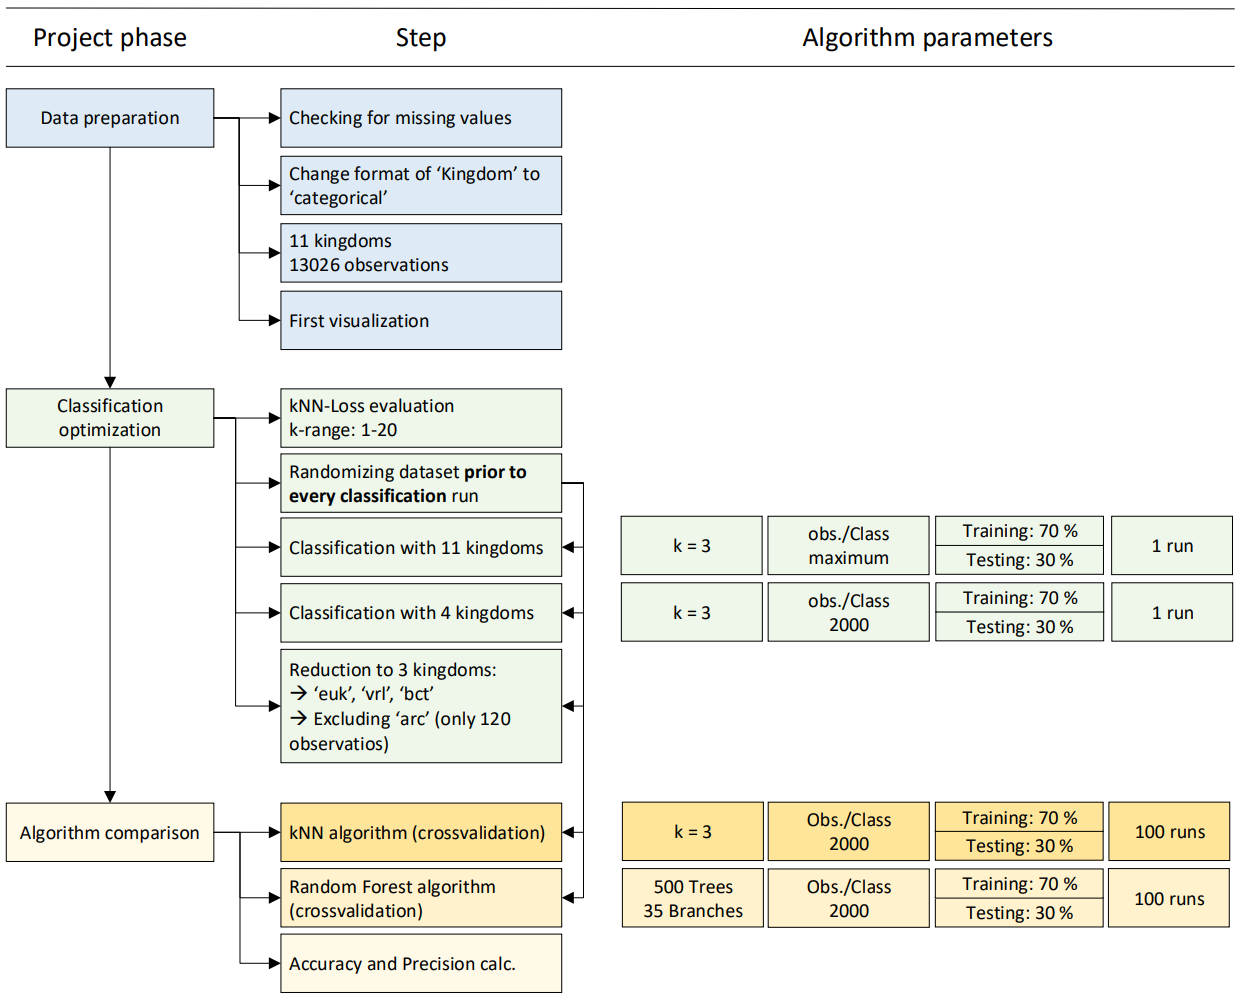

**Figure 2: **Project overview and parameter set-up for training and testing data. The Project is divided into three main parts: I) Data preparation, II) optimization of Classification with kNN algorithm and III) comparison of kNN and Naive Bayes algorithm. A ration of 70 % training and 30 % testing data was used in every approach.[Fgure created with MS Visio Professional]

### 4.1 Data preparation

In the first phase of this project, the preparation of the dataset was obtained. Therefore a check for missing values was performed. Three missing values in a total of two observations were detected. These two incomplete observations were excluded from the dataset. In a second step, the format of the first column in the dataset (Kingdom) was changed to ‘categorical’. To get a first impression about the distribution of the observations in the dataset, the data was plotted. This showed, that the entries are not randomly organized in the native form of the dataset. In total 13026 observations organized in 11 kingdoms were passed for algorithm implementation.

### 4.2 Optimization of classification

Due to highly variable numbers of observations in the 11 kingdoms, most of the taxonomically separated observations were combined to get more data per class for a sufficient performing algorithm. As an example, the number of observations in the domain of archaea amounts to 126, where the domain of bacteria counts more than 2000 observations. 

To prevent this unfair distribution of observations for every kingdom, the final classifications were performed with a total of three classes: Eukarya (euk), bacteria (bct), and virus (vrl). Therefore the kingdoms were assembled as seen in Figure 1. Furthermore, from every class, only 2000 observations were used for the algorithm implementation. As there are 6912 observations in the domains eukarya, 2919 in bacteria and 3051 in virus, the random sampling of 2000 observations in each domain leads to a variation in the selected data. This leads to an equal weighting of all three classes. In this optimizations are all performed with the kNN algorithm. 

In this report, 70% of the selected data per class was used for training, and 30% for testing. The allocation of the data to the training and testing dataset was performed by random.

### 4.3 Comparison of kNN and Random Forest algorithm 

In the final project phase, the comparison of the already implemented kNN algorithm is performed to the Random Forest algorithm. To ensure comparability, in every run, both algorithms get the same set of 2000 observations per class. For the Random Forest algorithm, a total of 500 trees with the optimal number of branches of 35 was used.[4] The kNN algorithm was performed with a k-value of 3 (determined with kNN-loss evaluation). The final visualization was achieved in a barplot. The comparison of the two algorithms was performed on the precision and accuracy calculation for both methods.

## 5. Experiments

The total running time of this programm is about  ~35 min.

### 5.1 Data preparation

#### Cleaning workspace and load data into matlab.

%% Cleaning and loading data into matlab
close all,clear, clc;
codonusage =  readtable('codon_usage.csv');

#### Data Preparation

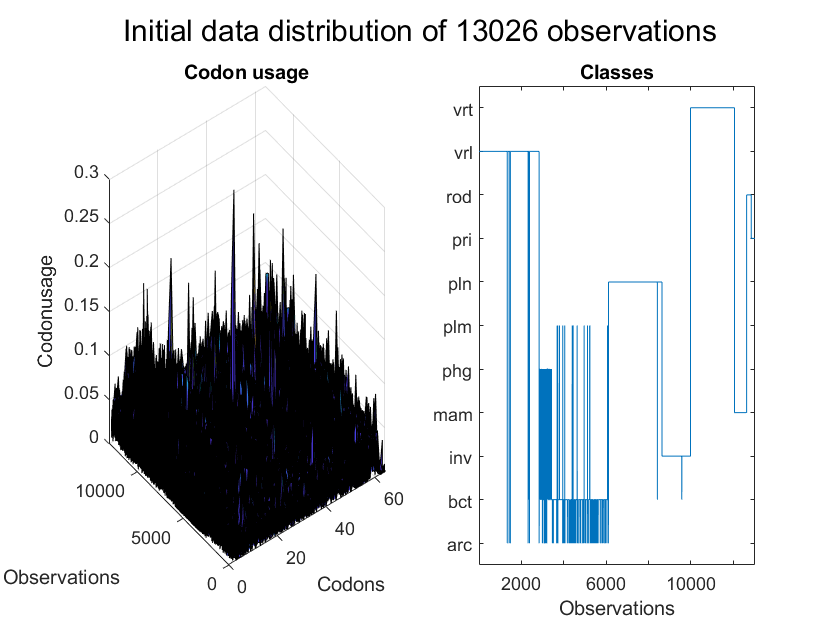

%% Data inspection
%separating needed data
data = codonusage(:,[1,6:end]);

%Change format of 'Kingdom' to categorical
data.Kingdom = categorical(data.Kingdom);

%Check for missing values 
missing = sum(sum(ismissing(data)));
% 3 enteries are missing these enteries are found in two observations 
% which are removed 

%get index of missing data 
badEntry = ismissing(data);
badRow = any(badEntry,2);
data = data(~badRow, :);

%First visualization
xValues = table2array(data(:,2:end));
yValues = categorical(table2array(data(:,1)));
figure()
subplot(1,2,1)
surf(xValues)
xlabel('Codons')
ylabel('Observations')
zlabel('Codonusage')
title('Codon usage')
subplot(1,2,2)
plot(yValues)
xlabel('Observations')
xlim([1, length(xValues)])
title('Classes')
sgtitle(['Initial data distribution of ', num2str(length(xValues)), ' observations'])

### 5.2 Classification optimization with kNN algorithm

- Removed Missing Data

- modified "Kindom" to be categorial Data for later classification

- Data seems to be more or less ordered in regards to 'Kingdom'

#### kNN-Loss evaluation for k range 1 to 20

%% kNN Classifier Qualitycheck ~ 2min runtime
crossvalloss= [];
i = 4;
for k = 1:20 
    i = i + 1;
    if i == 5
        disp(['Working: ',num2str((k-1)/20*100),'% done'])
        i = 0;
    end
    Modl         = fitcknn(xValues,yValues,'NumNeighbors',k); 
    cvModl       = crossval(Modl);
    cvMdlloss    = kfoldLoss(cvModl);
    crossvalloss = cat(1, crossvalloss, [k cvMdlloss]);
   
end

Working: 0% done
Working: 25% done
Working: 50% done
Working: 75% done


#### Ploting results of kNN Loss evaluation

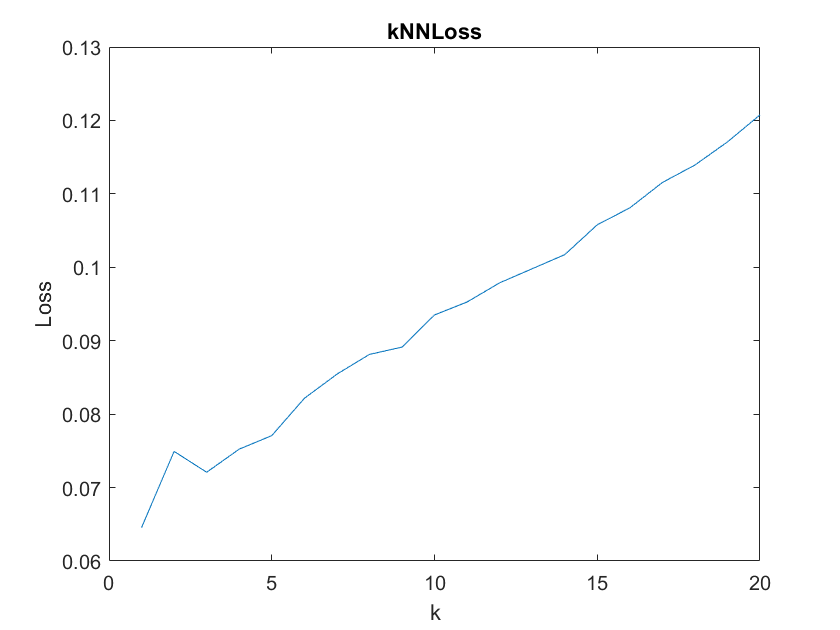

%% Ploting kNN Loss
figure()
plot(crossvalloss(:,1),crossvalloss(:,2))
title('kNNLoss')
xlabel('k')
ylabel('Loss')

A value for k = 3 was chosen due to the smalles loss after k = 1. Further the usage of only one neighbor is not recommended as this can lead to unstable classification.[5]

#### Classification with 11 Kingdoms

- Testing with 30% of the data

- k = 3 as determined by Loss evaluation

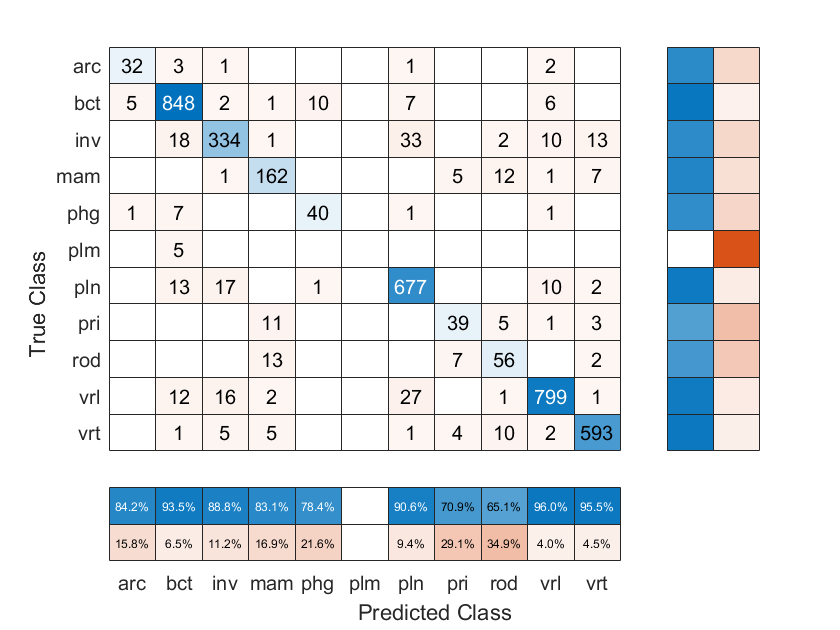

%% kNN classifier
%Parameters for kNN Classifier
%------------
data = data;
TrainingPercent = 0.7;
kTest = 3;

%indexing
randindex  = randperm(size(data,1));
trainindex = randindex(1:round((size(data,1)*(TrainingPercent))));
testindex  = randindex(length(trainindex)+1:end);

%data choosing for training
train = data(trainindex,:);

%data choosing for testing
xtest  = data(testindex,2:end);
ytest  = categorical(data(testindex,1).Kingdom);

%creating the model
model = fitcknn(train,'Kingdom', 'NumNeighbors', kTest);

%predction
yprediction = predict(model,xtest);
chart = confusionchart(ytest,yprediction);
chart.NormalizedValues;
chart.RowSummary = 'row-normalized';
chart.ColumnSummary = 'column-normalized';

Plot indicates, that the observation number for the eleven classes are not  not evenly distributed ant thus unfairly wighted in the training of the model. Therfore further optimizations to the data was performed:

- The Class plm was excluded since it only shows 18 enteries

- pln,vrt,inv,man,rod, and pri as euk combined since they belong to this kingdom of eukaryotes

- phg was added to vrl since phages are bacterial viruses 

%excluding plm
plm = find(data.Kingdom=='plm');
data(plm,:) = [];

%combining pln,vrt,inv,man,rod, and pri as euk
%get inices
pln = find(data.Kingdom == 'pln');
inv = find(data.Kingdom == 'inv');
vrt = find(data.Kingdom == 'vrt');
mam = find(data.Kingdom == 'mam');
rod = find(data.Kingdom == 'rod');
pri = find(data.Kingdom == 'pri');
%change class
data.Kingdom(pln) = 'euk';
data.Kingdom(inv) = 'euk';
data.Kingdom(vrt) = 'euk';
data.Kingdom(mam) = 'euk';
data.Kingdom(rod) = 'euk';
data.Kingdom(pri) = 'euk';

%adding phg to vrl
phg = find(data.Kingdom == 'phg');
data.Kingdom(phg) = 'vrl';

%new number of classes is 4
unique(data.Kingdom)

ans = 4×1 categorical array
     arc 
     bct 
     vrl 
     euk 


%save data in new variable
newdata = data;
newdata.Kingdom = setcats(newdata.Kingdom,{'arc','bct','vrl','euk'});
struct(newdata.Kingdom);

# entfernen 

#### Checking kNN with newly matched classes

%% New Data kNN Classifier Qualitycheck ~2min runtime

% find k for minimal loss
crossvalloss= [];
xValues = newdata(:,2:end);
nyValues = newdata.Kingdom;
i = 4;
for k = 1:20 
    i = i + 1;
    if i == 5
        disp(['Working: ',num2str((k-1)/20*100),'% done'])
        i = 0;
    end
    Mdl          = fitcknn(xValues,nyValues,'NumNeighbors',k); 
    cvMdl        = crossval(Mdl);
    cvMdlloss    = kfoldLoss(cvMdl);
    crossvalloss = cat(1, crossvalloss, [k cvMdlloss]);
end

Working: 0% done
Working: 25% done
Working: 50% done
Working: 75% done


% determin the minimal loss
min(crossvalloss(:,2))

ans = 0.0297

- k = 3 was choosen due to smallest stability 

#### kNN classification of new dataset with 4 kingdoms 

-  k = 3

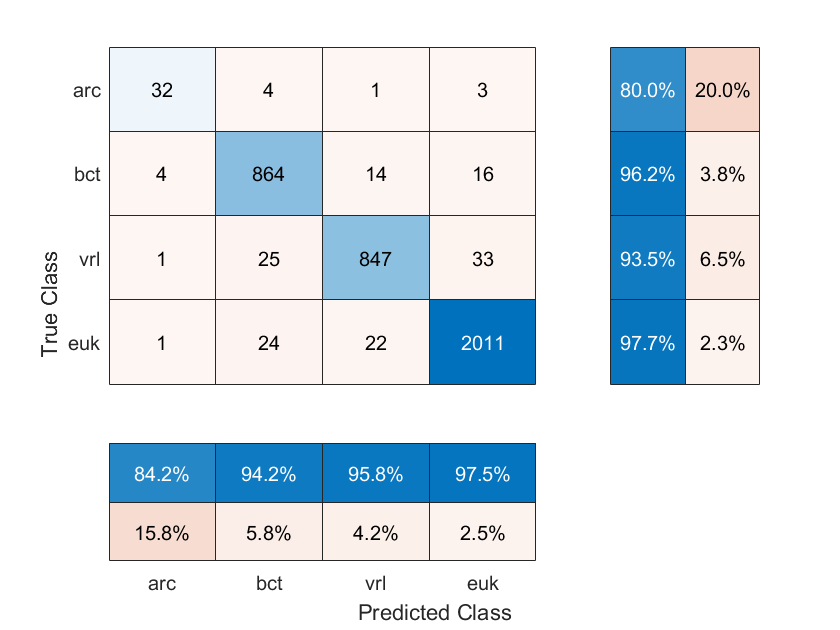

%------------------------------
data = newdata;
TrainingPercent = 0.7;
kTest = 3;

%indexing
randindex  = randperm(size(data,1));
trainindex = randindex(1:round((size(data,1)*(TrainingPercent))));
testindex  = randindex(length(trainindex)+1:end);

%data choosing for training
train = data(trainindex,:);

%data choosing for testing
xtest  = data(testindex,2:end);
ytest  = categorical(data(testindex,1).Kingdom);

%creating the model
model = fitcknn(train,'Kingdom', 'NumNeighbors', kTest);

%predction
yprediction = predict(model,xtest);
chart = confusionchart(ytest,yprediction);
chart.NormalizedValues;
chart.RowSummary = 'row-normalized';
chart.ColumnSummary = 'column-normalized';

chart;  

Distribution of data is not even therfore the training data should be equaly distributed which is why arc is removed from dataset because it has to few observations. 

For the fina dataset a fair weighting of the remaining three classes is targeted. THerfore randomly 2000 observations are chosen by for every Kingdom in every classification run. The 70 % training and 30 % testing data split is performed on these 2000 observations.

#### Finaldataset initialisation

%% create newestdataset
%remove arc
newdata(find(newdata.Kingdom == 'arc'),:) = [];
newestdata = newdata;
%set new categories
newestdata.Kingdom = setcats(newestdata.Kingdom,{'bct','vrl','euk'});
struct(newestdata.Kingdom)

ans = struct with fields:
    defaultCodesClass: 'uint8'
         missingLabel: '<missing>'
            undefCode: 0
           undefLabel: '<undefined>'
     maxNumCategories: 2.8147e+14
        categoryNames: {3×1 cell}
                codes: [12882×1 uint8]
          isProtected: 0
            isOrdinal: 0


### 5.3 Algorithm comparison kNN vs Random Forest with 3 kingdoms over 100 iterations 

- 100 iterations

- also 30% Testingdata with each class evenly distirbuted

- same randomly chosen dataset for both algorithms

- max Branch # is set to 35 according according to literature reference [4]

- determin pression and accuracy of both models and compare

1 Runs DONE out of 100


6 Runs DONE out of 100


11 Runs DONE out of 100


16 Runs DONE out of 100


21 Runs DONE out of 100


26 Runs DONE out of 100


31 Runs DONE out of 100


36 Runs DONE out of 100


41 Runs DONE out of 100


46 Runs DONE out of 100


51 Runs DONE out of 100


56 Runs DONE out of 100


61 Runs DONE out of 100


66 Runs DONE out of 100


71 Runs DONE out of 100


76 Runs DONE out of 100


81 Runs DONE out of 100


86 Runs DONE out of 100


91 Runs DONE out of 100


96 Runs DONE out of 100


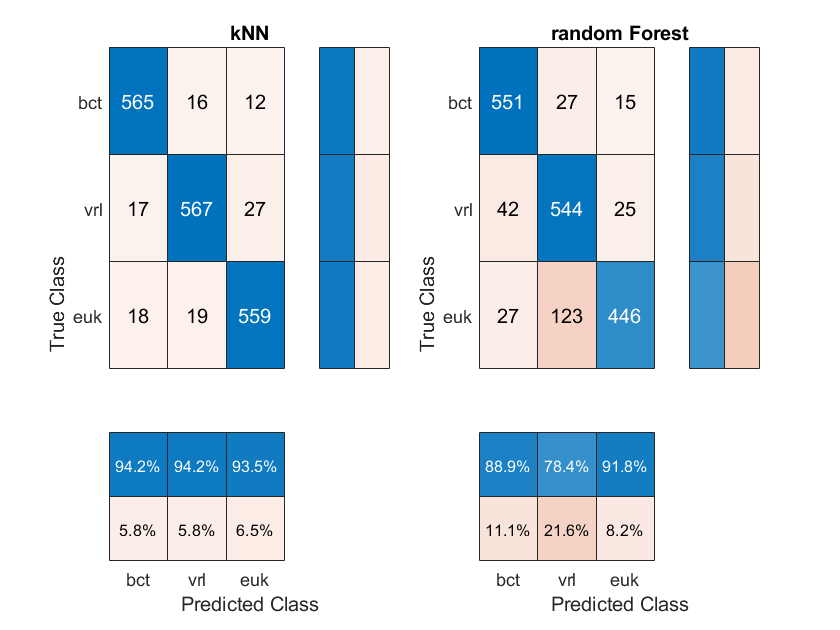


%Number to weight all data evenly
NumCU = 2000;          % Should be lower then 2700
Crossval = 0.7;
kTest = 3;
Runs = 100;
NumberOfTrees = 500;   
Branches = 35;         %taken form literature [4]

%Initializations (please dont touch)
kNNacc = [];
kNNpre = [];
NBacc = [];
NBpre = [];
Forestypredciton = [];
%get individual data for each class
bct = newestdata(find(newestdata.Kingdom == 'bct'),:);
vrl = newestdata(find(newestdata.Kingdom == 'vrl'),:);
euk = newestdata(find(newestdata.Kingdom == 'euk'),:);

%%%
%start for loop
%%%
counter = 4;
for i = 1:Runs

if counter == 5
    fprintf('%i Runs DONE out of %i\n', (i-1),Runs)
    counter = 0;
end
counter = counter + 1;
%picking data
%-----------%
%getin randomized and equaly weight bacterial data:
%random in species
rnumbrs = randperm(size(bct,1));
%choose indexes
rindex = rnumbrs(1:NumCU);
%get data
rbct = bct(rindex,:);

%random in species
rnumbrs = randperm(size(vrl,1));
%choose indexes
rindex = rnumbrs(1:NumCU);
%get data
rvrl = vrl(rindex,:);


%random in species
rnumbrs = randperm(size(euk,1));
%choose indexes
rindex = rnumbrs(1:NumCU);
%get data
reuk = euk(rindex,:);

%Create final randomicesed dataset 
testdata  = [rbct;rvrl;reuk];
testindex = randperm(size(testdata,1));
testdata = testdata(testindex,:);
TyValues = testdata.Kingdom;

%-----------------------------------------------

data = testdata;

%indexing
randindex  = randperm(size(data,1));
trainindex = randindex(1:round((size(data,1)*(Crossval))));
testindex  = randindex(length(trainindex)+1:end);

%data choosing for training
train = data(trainindex,:);

%data choosing for testing
xtest  = data(testindex,2:end);
ytest  = categorical(data(testindex,1).Kingdom);


%-----------------------------------------------%
%                 Classifiers                   %
%-----------------------------------------------%
%knn 
%creating the models
kNNmodel = fitcknn(train,'Kingdom', 'NumNeighbors', kTest);
%predctions
kNNyprediction  = predict(kNNmodel,xtest);


%Random Forest
NBmodel  = TreeBagger(NumberOfTrees,train,'Kingdom','MaxNumSplits',Branches); %Max Branch number was choosen from experience by [4]
%prediction
NByprediction   = predict(NBmodel,xtest);

%Plots
subplot(1,2,1)
Ncm = confusionchart(ytest,kNNyprediction);
Ncm.NormalizedValues;
Ncm.RowSummary = 'row-normalized';
Ncm.ColumnSummary = 'column-normalized';
title('kNN')

subplot(1,2,2)
Ncm2 = confusionchart(ytest,categorical(NByprediction));
Ncm2.NormalizedValues;
Ncm2.RowSummary = 'row-normalized';
Ncm2.ColumnSummary = 'column-normalized';
title('random Forest');

%------------------------------------------------
%           Presission and Accuracy              
%------------------------------------------------
% NB 
% %Bacteria
TPbctNB   = Ncm2.NormalizedValues(1,1);
FPbctNB   = sum(Ncm2.NormalizedValues(1,2:end));
TNbctNB   = sum(sum(Ncm2.NormalizedValues(2:end,2:end)));
FNbctNB   = sum(Ncm2.NormalizedValues(2:end,1));

accBctNB = (TPbctNB + TNbctNB)/(TPbctNB+FPbctNB+TNbctNB+FNbctNB);
preBctNB = TPbctNB/(TPbctNB+ FPbctNB);

%Viruses
TPvrlNB   = Ncm2.NormalizedValues(2,2);
FPvrlNB   = Ncm2.NormalizedValues(2,1)+Ncm2.NormalizedValues(2,3);
TNvrlNB   = Ncm2.NormalizedValues(1,1)+Ncm2.NormalizedValues(1,3)+Ncm2.NormalizedValues(3,1)+Ncm2.NormalizedValues(3,3);
FNvrlNB   = Ncm2.NormalizedValues(1,2)+Ncm2.NormalizedValues(3,2);

accVrlNB = (TPvrlNB + TNvrlNB)/(TPvrlNB+FPvrlNB+TNvrlNB+FNvrlNB);
preVrlNB = TPvrlNB/(TPvrlNB+ FPvrlNB);

%Eukarya
TPeukNB   = Ncm2.NormalizedValues(3,3);
FPeukNB   = sum(Ncm2.NormalizedValues(3,1:2));
TNeuNB    = sum(sum(Ncm2.NormalizedValues(1:2,1:2)));
FNeukNB   = sum(Ncm2.NormalizedValues(1:2,3));

accEukNB = (TPeukNB + TNeuNB)/(TPeukNB+FPeukNB+TNeuNB+FNeukNB);
preEukNB = TPeukNB/(TPeukNB+ FPeukNB);

%-----------
%-----------
% kNN
TPbctkNN   = Ncm.NormalizedValues(1,1);
FPbctkNN   = sum(Ncm.NormalizedValues(1,2:end));
TNbctkNN   = sum(sum(Ncm.NormalizedValues(2:end,2:end)));
FNbctkNN   = sum(Ncm.NormalizedValues(2:end,1));

accBctkNN = (TPbctkNN + TNbctkNN)/(TPbctkNN+FPbctkNN+TNbctkNN+FNbctkNN);
preBctkNN = TPbctkNN/(TPbctkNN+ FPbctkNN);

%Viruses
TPvrlkNN   = Ncm.NormalizedValues(2,2);
FPvrlkNN   = Ncm.NormalizedValues(2,1)+Ncm.NormalizedValues(2,3);
TNvrlkNN   = Ncm.NormalizedValues(1,1)+Ncm.NormalizedValues(1,3)+Ncm.NormalizedValues(3,1)+Ncm.NormalizedValues(3,3);
FNvrlkNN   = Ncm.NormalizedValues(1,2)+Ncm.NormalizedValues(3,2);

accVrlkNN = (TPvrlkNN + TNvrlkNN)/(TPvrlkNN+FPvrlkNN+TNvrlkNN+FNvrlkNN);
preVrlkNN = TPvrlkNN/(TPvrlkNN+ FPvrlkNN);

%Eukarya
TPeukkNN   = Ncm.NormalizedValues(3,3);
FPeukkNN   = sum(Ncm.NormalizedValues(3,1:2));
TNeukNN    = sum(sum(Ncm.NormalizedValues(1:2,1:2)));
FNeukkNN   = sum(Ncm.NormalizedValues(1:2,3));

accEukkNN = (TPeukkNN + TNeukNN)/(TPeukkNN+FPeukkNN+TNeukNN+FNeukkNN);
preEukkNN = TPeukkNN/(TPeukkNN+ FPeukkNN);

%------------------------------------------%
%         Validation of the Model          %
%------------------------------------------%

kNNaccAD = [accBctkNN,accVrlkNN,accEukkNN];
kNNpreAD = [preBctkNN,preVrlkNN,preEukkNN];
NBaccAD  = [accBctNB,accVrlNB,accEukNB];
NBpreAD  = [preBctNB,preVrlNB,preEukNB];
kNNacc   = [kNNacc;kNNaccAD];
kNNpre   = [kNNpre;kNNpreAD];
NBacc    = [NBacc;NBaccAD];
NBpre    = [NBpre;NBpreAD];
end

## Algorithm Comparison kNN vs. Random Forest in bar plots

From previous results the following comparison can be visualized

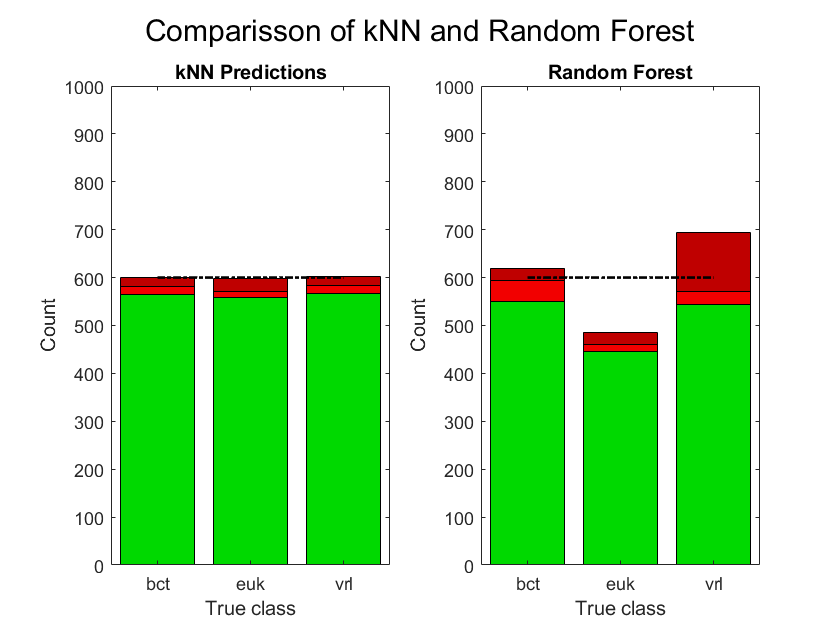

%geting the models
kNN = Ncm.NormalizedValues;
NB = Ncm2.NormalizedValues;

%True values kNN
%bct
kNNTbctH = Ncm.NormalizedValues(1,1);
kNNTbctvrl = Ncm.NormalizedValues(1,2);
kNNTbcteuk = Ncm.NormalizedValues(1,3);
%vrl
kNNTvrlH = Ncm.NormalizedValues(2,2);
kNNTvrlbct = Ncm.NormalizedValues(2,1);
kNNTvrleuk = Ncm.NormalizedValues(2,3);
%euk
kNNTeukH = Ncm.NormalizedValues(3,3);
kNNTeukeuk = Ncm.NormalizedValues(3,1);
kNNTeukvrl = Ncm.NormalizedValues(3,2);

%Predicted values kNN
%bct
kNNPbctH = Ncm.NormalizedValues(1,1);
kNNPbctvrl = Ncm.NormalizedValues(2,1);
kNNPbcteuk = Ncm.NormalizedValues(3,1);
%vrl
kNNPvrlbct = Ncm.NormalizedValues(1,2);
kNNPvrlH = Ncm.NormalizedValues(2,2);
kNNPvrleuk = Ncm.NormalizedValues(3,2);
%euk
kNNPeukbct = Ncm.NormalizedValues(1,3);
kNNPeukvrl = Ncm.NormalizedValues(2,3);
kNNPeukH = Ncm.NormalizedValues(3,3);


%True values Random Forest
%bct
NBTbctH = Ncm2.NormalizedValues(1,1);
NBTbctvrl = Ncm2.NormalizedValues(1,2);
NBTbcteuk = Ncm2.NormalizedValues(1,3);
%vrl
NBTvrlH = Ncm2.NormalizedValues(2,2);
NBTvrlbct = Ncm2.NormalizedValues(2,1);
NBTvrleuk = Ncm2.NormalizedValues(2,3);
%euk
NBTeukH = Ncm2.NormalizedValues(3,3);
NBTeukeuk = Ncm2.NormalizedValues(3,1);
NBTeukvrl = Ncm2.NormalizedValues(3,2);

%Predicted values Random Forest
%bct
NBPbctH = Ncm2.NormalizedValues(1,1);
NBPbctvrl = Ncm2.NormalizedValues(2,1);
NBPbcteuk = Ncm2.NormalizedValues(3,1);
%vrl
NBPvrlbct = Ncm2.NormalizedValues(1,2);
NBPvrlH = Ncm2.NormalizedValues(2,2);
NBPvrleuk = Ncm2.NormalizedValues(3,2);
%euk
NBPeukbct = Ncm2.NormalizedValues(1,3);
NBPeukvrl = Ncm2.NormalizedValues(2,3);
NBPeukH = Ncm2.NormalizedValues(3,3);

%-----------------------------%
% Combining Values to Vectors %
%-----------------------------%
kNNPlot = [kNNPbctH,kNNPbctvrl,kNNPbcteuk; kNNPvrlH,kNNPvrlbct,kNNPvrleuk; kNNPeukH,kNNPeukbct, kNNPeukvrl];
NBPlot = [NBPbctH,NBPbctvrl,NBPbcteuk;NBPvrlH,NBPvrlbct,NBPvrleuk;NBPeukH,NBPeukbct,NBPeukvrl];

label = cellstr(['Predicted bct';'Predicted vrl';'Predicted euk']);
labels = categorical(label);
class = cellstr(['bct';'vrl';'euk']);
classes = categorical(class);

%Ploting
subplot(1,2,1)
b1 = bar(classes,kNNPlot, 'stacked','FaceColor','flat');
b1(1).CData = [0,0.85,0];
b1(2).CData = [0.95,0,0];
b1(3).CData = [0.75,0,0];
% legend(labels, 'Location','northwest')
ylim([0,1000])
title('kNN Predictions')
ylabel('Count')
xlabel('True class')
hold on
xlim=get(gca,'xlim');
plot(xlim,[600 600], 'k-.','lineWidth',1.3)
hold off

subplot(1,2,2)
b2 = bar(classes,NBPlot, 'stacked','FaceColor','flat');
b2(1).CData = [0,0.85,0];
b2(2).CData = [0.95,0,0];
b2(3).CData = [0.75,0,0];
% legend(labels, 'Location','northwest')
ylim([0,1000])
title('Random Forest')
ylabel('Count')
xlabel('True class')
hold on
xlim=get(gca,'xlim');
plot(xlim,[600 600], 'k-.','lineWidth',1.3)
hold off
sgtitle('Comparisson of kNN and Random Forest')

% Display accuracy and precision for both models
kNNaccMean = mean(kNNacc);
kNNpreMean = mean(kNNpre);
rForestaccMean  = mean(NBacc); 
rForestpreMean  = mean(NBpre);

kNN_Results =[kNNaccMean,mean(kNNaccMean);kNNpreMean,mean(kNNpreMean)];
kNN_Results = dataset({kNN_Results 'bct','vrl','euk','overall'}, ...
              'obsnames', {'Accuracy','Precision'});

rForest_Results = [rForestaccMean,mean(rForestaccMean);rForestpreMean,mean(rForestpreMean)];
rForest_Results = dataset({rForest_Results 'bct','vrl','euk','overall'}, ...
              'obsnames', {'Accuracy','Precision'});

kNN_Results,rForest_Results

kNN_Results =                  bct        vrl        euk        overall
    Accuracy     0.96697    0.96102    0.96213    0.96337
    Precision     0.9646    0.93123    0.93955    0.94513


rForest_Results =                  bct        vrl        euk        overall
    Accuracy     0.93601    0.88302    0.89856    0.90586
    Precision     0.9371    0.89812    0.74142    0.85888


## References

[1]    Campbell et al., 2016: Campbell Biologie , ISBN: 978-3-86894-259-0 978-3-86326-725-4.

[2]    Cannarozzi & Schneider, 2012: Codon evolution: mechanisms and models, ISBN: 978-0-19-960116-5.

[3]    [https://www.wsl.ch/de/projekte/charakterisierung-der-biodiversitaet-in-waldboeden-mittels-dna-metabarcoding.html](https://www.wsl.ch/de/projekte/charakterisierung-der-biodiversitaet-in-waldboeden-mittels-dna-metabarcoding.html), [08.12.2020].

[4]    Khomtchouk et al., 2020CODON USAGE BIAS LEVELS PREDICT TAXONOMIC IDENTITY AND GENETIC COMPOSITION, doi:             

        [https://doi.org/10.1101/2020.10.26.356295](https://doi.org/10.1101/2020.10.26.356295) 

[5]    Barber, 2020: Bayesian Reasoning and Machine Learning, [www.cs.ucl.ac.uk/staff/D.Barber/brml.](www.cs.ucl.ac.uk/staff/D.Barber/brml.)

[6]   Flach,  2012: MACHINE LEARNING - The Art and Science of Algorithmsthat Make Sense of Data, ISBN: 978-1-107-09639-4.